## Power vs Load Resistance

% File path
filename = 'Integration_3.xlsx';  % Make sure the file is in your current folder

% Read data from sheet (assuming only one sheet or you know the sheet name)
sheetName = '75kHz';  % Replace with your sheet name if different
T = readtable(filename, 'Sheet', sheetName, 'Range', 'A3:N100');  % Start from row 3

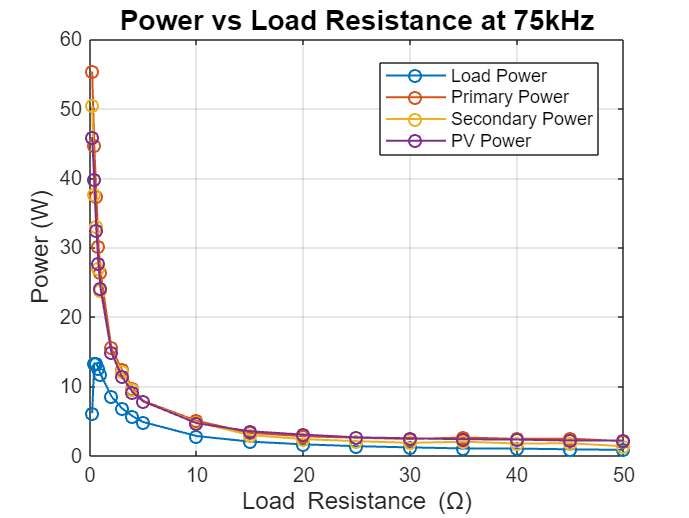


% Extract relevant columns
load_res = T{:,1};  % Load resistance
P_load = T{:,4};    % Load power (assumed column 4)
P_primary = T{:,8}; % Primary power
P_secondary = T{:,11}; % Secondary power
P_PV = T{:,14};     % PV power

% Plot
figure;
plot(load_res, P_load, '-o', 'LineWidth', 1, 'DisplayName', 'Load Power'); hold on;
plot(load_res, P_primary, '-o', 'LineWidth', 1, 'DisplayName', 'Primary Power');
plot(load_res, P_secondary, '-o', 'LineWidth', 1, 'DisplayName', 'Secondary Power');
plot(load_res, P_PV, '-o', 'LineWidth', 1, 'DisplayName', 'PV Power');
hold off;

% Formatting
xlabel('Load Resistance (\Omega)', 'FontSize', 12);
ylabel('Power (W)', 'FontSize', 12);
title(['Power vs Load Resistance at ' sheetName], 'FontSize', 14);
legend('Location', 'best');
grid on;

## Output Power vs Load Resistance

% File name and sheet
filename = 'Integration_3.xlsx';
sheetName = '75kHz';  % Change as needed

% Read data (starting from row 3)
T = readtable(filename, 'Sheet', sheetName, 'Range', 'A3:N100');

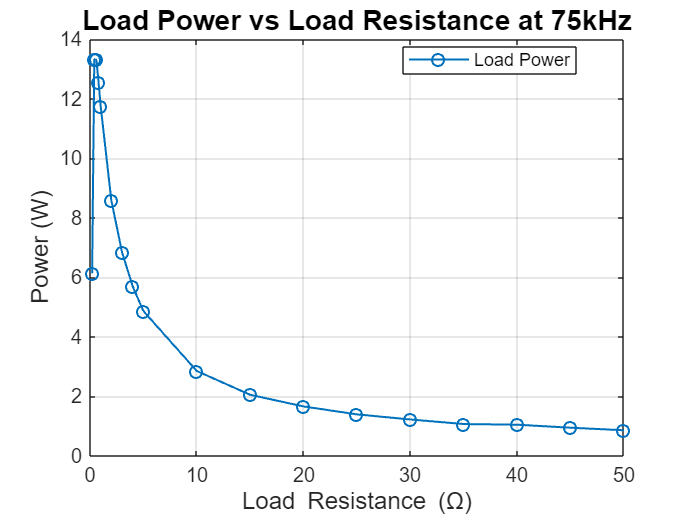


% Extract data
load_res = T{:,1};         % Load resistance
P_load = T{:,4};           % Load Power

%% Plot 1: Power at Load vs Load Resistance
figure;
plot(load_res, P_load, '-o', 'LineWidth', 1, 'DisplayName', 'Load Power');
xlabel('Load Resistance (\Omega)', 'FontSize', 12);
ylabel('Power (W)', 'FontSize', 12);
title(['Load Power vs Load Resistance at ' sheetName], 'FontSize', 14);
grid on;
legend('Location', 'best');

## Stage Efficiencies vs Load Resistance

% File name and sheet
filename = 'Integration_3.xlsx';
sheetName = '75kHz';  % Change as needed

% Read data (starting from row 3)
T = readtable(filename, 'Sheet', sheetName, 'Range', 'A3:N100');

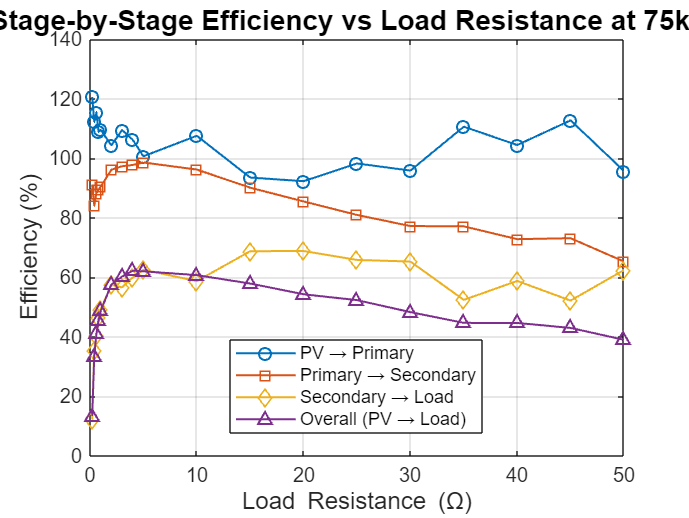


% Extract data
load_res = T{:,1};         % Load resistance
P_PV = T{:,14};            % PV Power (V*I)
P_primary = T{:,8};        % Primary Power
P_secondary = T{:,11};     % Secondary Power
P_load = T{:,4};           % Load Power

% Efficiency calculations (with division checks)
eff_pv_to_primary = (P_primary ./ P_PV) * 100;
eff_primary_to_secondary = (P_secondary ./ P_primary) * 100;
eff_secondary_to_load = (P_load ./ P_secondary) * 100;
eff_overall = (P_load ./ P_PV) * 100;

% Replace NaNs and Infs from division by zero with zeros
eff_pv_to_primary(~isfinite(eff_pv_to_primary)) = 0;
eff_primary_to_secondary(~isfinite(eff_primary_to_secondary)) = 0;
eff_secondary_to_load(~isfinite(eff_secondary_to_load)) = 0;
eff_overall(~isfinite(eff_overall)) = 0;

%% Plot Efficiencies vs Load Resistance
figure;
plot(load_res, eff_pv_to_primary, '-o', 'LineWidth', 1, 'DisplayName', 'PV → Primary'); hold on;
plot(load_res, eff_primary_to_secondary, '-s', 'LineWidth', 1, 'DisplayName', 'Primary → Secondary');
plot(load_res, eff_secondary_to_load, '-d', 'LineWidth', 1, 'DisplayName', 'Secondary → Load');
plot(load_res, eff_overall, '-^', 'LineWidth', 1, 'DisplayName', 'Overall (PV → Load)');
hold off;

xlabel('Load Resistance (\Omega)', 'FontSize', 12);
ylabel('Efficiency (%)', 'FontSize', 12);
title(['Stage-by-Stage Efficiency vs Load Resistance at ' sheetName], 'FontSize', 14);
legend('Location', 'best');
grid on;

## Overall Efficiency

% File name and sheet
filename = 'Integration_3.xlsx';
sheetName = '75kHz';  % Change as needed

% Read data (starting from row 3)
T = readtable(filename, 'Sheet', sheetName, 'Range', 'A3:N100');

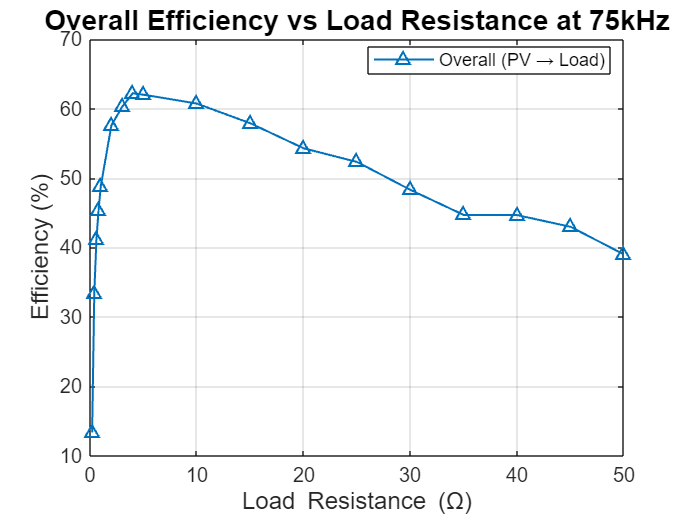


% Extract data
load_res = T{:,1};         % Load resistance
P_PV = T{:,14};            % PV Power (V*I)
P_primary = T{:,8};        % Primary Power
P_secondary = T{:,11};     % Secondary Power
P_load = T{:,4};           % Load Power

% Efficiency calculations (with division checks)
eff_overall = (P_load ./ P_PV) * 100;

% Replace NaNs and Infs from division by zero with zeros
eff_overall(~isfinite(eff_overall)) = 0;

%% Plot Efficiencies vs Load Resistance
figure;
plot(load_res, eff_overall, '-^', 'LineWidth', 1, 'DisplayName', 'Overall (PV → Load)'); hold on;
hold off;

xlabel('Load Resistance (\Omega)', 'FontSize', 12);
ylabel('Efficiency (%)', 'FontSize', 12);
title(['Overall Efficiency vs Load Resistance at ' sheetName], 'FontSize', 14);
legend('Location', 'best');
grid on;

## Efficiency Table

% File and sheet name
filename = 'Integration_3.xlsx';
sheetName = '75kHz';

% Read data
T = readtable(filename, 'Sheet', sheetName, 'Range', 'A3:N100');


% Extract relevant columns
load_res = T{:,1};         % Load resistance
P_PV = T{:,14};            % PV power
P_primary = T{:,8};        % Primary power
P_secondary = T{:,11};     % Secondary power
P_load = T{:,4};           % Load power

% Ensure all vectors are column vectors and same length
n = min([length(load_res), length(P_PV), length(P_primary), length(P_secondary), length(P_load)]);
load_res = load_res(1:n);
P_PV = P_PV(1:n);
P_primary = P_primary(1:n);
P_secondary = P_secondary(1:n);
P_load = P_load(1:n);

% Calculate efficiencies (prevent divide-by-zero)
eff_pv_to_primary = zeros(n,1);
eff_primary_to_secondary = zeros(n,1);
eff_secondary_to_load = zeros(n,1);
eff_overall = zeros(n,1);

for i = 1:n
    if P_PV(i) > 0
        eff_pv_to_primary(i) = (P_primary(i) / P_PV(i)) * 100;
        eff_overall(i) = (P_load(i) / P_PV(i)) * 100;
    end
    if P_primary(i) > 0
        eff_primary_to_secondary(i) = (P_secondary(i) / P_primary(i)) * 100;
    end
    if P_secondary(i) > 0
        eff_secondary_to_load(i) = (P_load(i) / P_secondary(i)) * 100;
    end
end

% Create and display the efficiency table
EfficiencyTable = table( ...
    load_res, ...
    eff_pv_to_primary, ...
    eff_primary_to_secondary, ...
    eff_secondary_to_load, ...
    eff_overall, ...
    'VariableNames', { ...
        'Load_Resistance_Ohm', ...
        'PV_to_Primary_Percent', ...
        'Primary_to_Secondary_Percent', ...
        'Secondary_to_Load_Percent', ...
        'Overall_Efficiency_Percent' ...
    });

disp(EfficiencyTable);

    Load_Resistance_Ohm    PV_to_Primary_Percent    Primary_to_Secondary_Percent    Secondary_to_Load_Percent    Overall_Efficiency_Percent
    ___________________    _____________________    ____________________________    _________________________    __________________________

            0.2                   120.57                       91.074                        12.176                         13.37          
            0.4                    112.2                       84.067                        35.436                        33.424          
            0.6                   115.38                       88.231                        40.367                        41.095          
            0.8                   108.93                       89.448                        46.527                        45.333

## Load Resistance vs Voltage/Current

% File and sheet
filename = 'Integration_3.xlsx';
sheetName = '75kHz';  % Change if needed

% Read data starting from row 3
T = readtable(filename, 'Sheet', sheetName, 'Range', 'A3:N100');

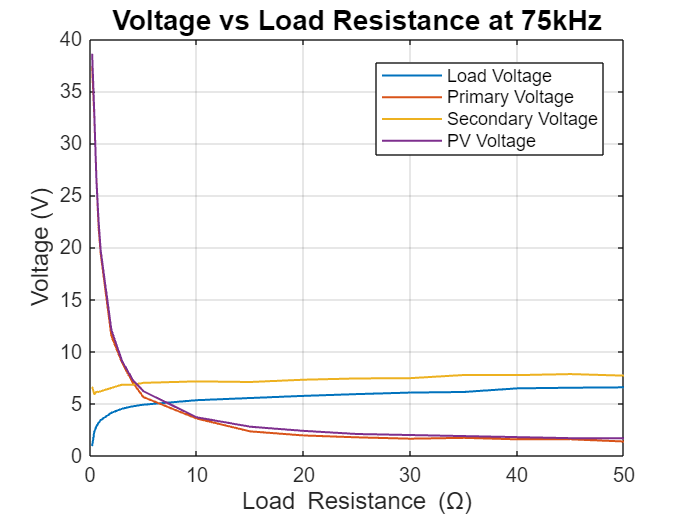


% Load Resistance
load_res = T{:,1};

% Voltages
V_load = T{:,2};
V_primary = T{:,6};
V_secondary = T{:,9};
V_PV = T{:,12};

% Currents
I_load = T{:,3};
I_primary = T{:,7};
I_secondary = T{:,10};
I_PV = T{:,13};

%% Plot: Load Resistance vs Voltage
figure;
plot(load_res, V_load, '-', 'LineWidth', 1, 'DisplayName', 'Load Voltage'); hold on;
plot(load_res, V_primary, '-', 'LineWidth', 1, 'DisplayName', 'Primary Voltage');
plot(load_res, V_secondary, '-', 'LineWidth', 1, 'DisplayName', 'Secondary Voltage');
plot(load_res, V_PV, '-', 'LineWidth', 1, 'DisplayName', 'PV Voltage');
hold off;
xlabel('Load Resistance (\Omega)', 'FontSize', 12);
ylabel('Voltage (V)', 'FontSize', 12);
title(['Voltage vs Load Resistance at ' sheetName], 'FontSize', 14);
legend('Location', 'best');
grid on;

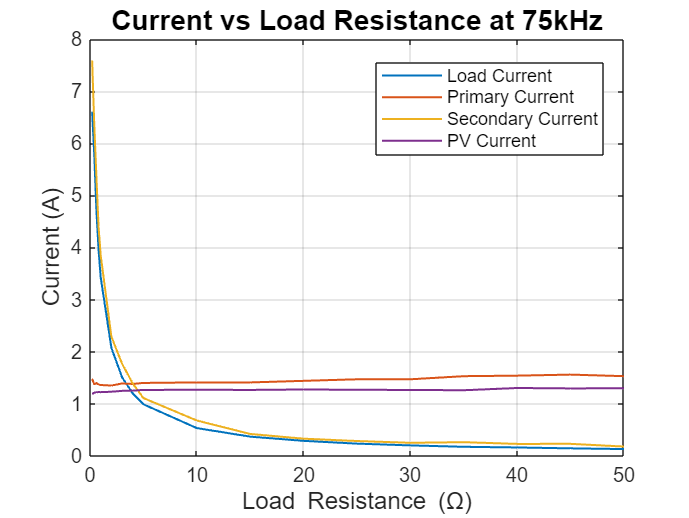


%% Plot: Load Resistance vs Current
figure;
plot(load_res, I_load, '-', 'LineWidth', 1, 'DisplayName', 'Load Current'); hold on;
plot(load_res, I_primary, '-', 'LineWidth', 1, 'DisplayName', 'Primary Current');
plot(load_res, I_secondary, '-', 'LineWidth', 1, 'DisplayName', 'Secondary Current');
plot(load_res, I_PV, '-', 'LineWidth', 1, 'DisplayName', 'PV Current');
hold off;
xlabel('Load Resistance (\Omega)', 'FontSize', 12);
ylabel('Current (A)', 'FontSize', 12);
title(['Current vs Load Resistance at ' sheetName], 'FontSize', 14);
legend('Location', 'best');
grid on;